# Fitting the Data

We can make the observations from scatter plots & histograms more formal by looking at correlation values and pdf curves.

## Correlation

The function `corr(x,y)` gives the pairwise correlation coefficient between the column vectors `x` and `y` (they have to be columns).

We can also get the coveted p-value by specifying two outputs. DISCLAIMER this sort of test isn't suitable for all data. Consult your friendly neighbourhood statistician if you're not sure.

The `corr` function can also be used to get a matrix of pairwise correlation coefficients of every column in a matrix. Let's create a matrix `X` with different linear functions in each column.

And look at the correlation coefficients

## Challenge

% CHALLENGE
% What happens to the correlation coefficients
% if you add Gaussian noise
% to the lines in the matrix X?


% HINT: randn(m,n) will create a m-by-n matrix 
% of Gaussian noise with mean 0 and std 1.

% Create Gaussian noise the same size as X


% Add noise to X

% Plot the 4 lines


% Get correlation


Challenge

% CHALLENGE
% What about non-linear data?
% Test the correlation with the function 

%x = t .^ idx;

Undefined function or variable 't'.


% Try using the rank correlation instead using
% corr(X,'type','Spearman')

% EXTENSION
% What about if you make the functions in X 
% sinusoidal instead of linear? 

% EXTENSION
% Check the correlation betweeen pedestrian counts at
% Bourke street from your previous code

## Clustering

The function `kmeans` is a good "quick and dirty" way to segment data into groups. We can make a toy example vector, `x` with two peaks in the histogram.

% make a vector of random numbers with 
% half centred around -10 and half around 10.


% use kmeans to find the clusters


We can plot the data separately using the cluster index

We can also get the centre point of each cluster

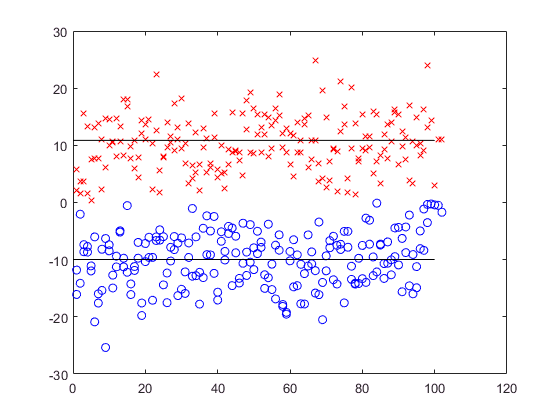

% a second output includes the centre points


% we can plot a line through the middle using the 
% line function


*Challenge*

%% CHALLENGE 
% Look up kmeans in the help documentation and use 
% it to cluster the pedestrian
% counts at Flinders street at 8am (Flinders8)
% into two or more groups.

% HINT your input should be the pedestrian 
% counts from the previous challenge: 

%% EXTENSION
% 1. Plot your two clusters as separate histograms
% 2. Include a vertical line on the graph marking the 
% center of the cluster (the function line() will help)
% 

%% EXTENSION
% Can you see any factors that are different between 
% the clusters? Check the day of the week.

## Probability

We can fit the probability density function to our histograms using a kernel-density estimation (`ksdensity`), or we can check the fit of specific distribution shapes, such as Gaussian, exponential, etc (`fitdist`).

Going to make some fake data using the `rand` command

Fit an exponential distribution

We get a distribution parameter and confidence bounds. The exponential distribution just has one parameter. You can always read more about the distribution by clicking the link in MATLAB.

We can check the estimate against the histogram

Challenge

% CHALLENGE
% Use fitdist to fit a normal distribution to 
% each of the clusters from the previous challenge
% (flinders street on the weekend and weekday)

% EXTENSION
% create a line plot of the estimated Gaussian
% distributions on top of the histograms
% HINT: you don't have to look up the equation for a 
% Gaussian pdf to plot one, you can use the
% function normpdf()

There are heaps of distributions included in the standard `fitdist` function, most of which I have never even heard of... Search the fitdist function.